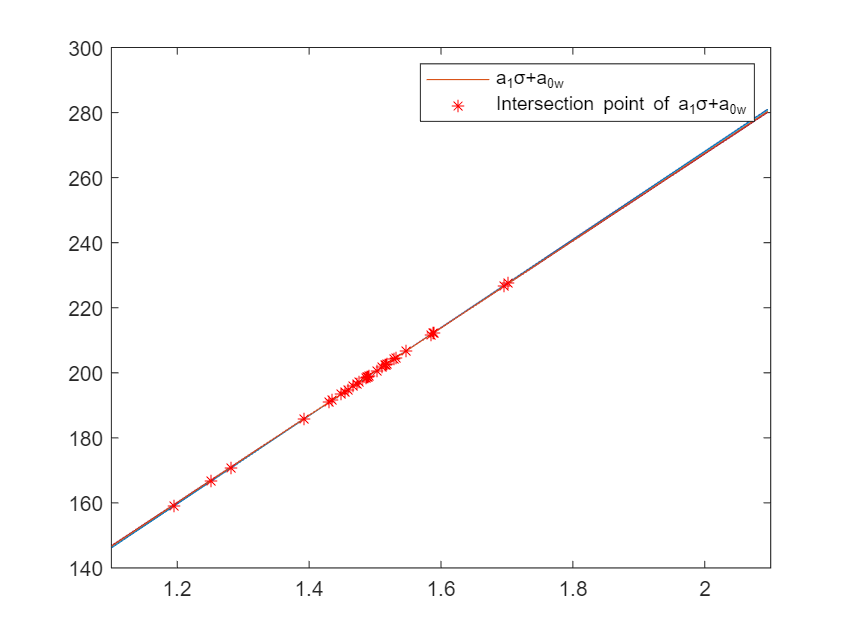

clear;clc;
format short g
spectrum = readtable("Isigma.xls","ReadVariableNames",false);
spectrum_frequency = (spectrum{:,1})';
[~, indix_min] = min(abs(spectrum_frequency-1.1));
[~, indix_max] = min(abs(spectrum_frequency-2.1));
spectrum_frequency = spectrum_frequency(indix_min:indix_max);
a1 = [135.2603 135.2870  135.3017 135.4530 134.8067 134.8686 133.7878 135.5223 134.3774];
a0 = [-2.5333 -2.5509 -2.5742 -2.7637 -1.8633 -1.9108 -0.3192 -2.9499 -1.1987];
for n =1:length(a1)
    y = a1(n).*spectrum_frequency+a0(n);
    h1 = plot(spectrum_frequency,y);
    hold on 
end
for i = 1:8
    for n = i+1:9
    [x1, y1] = linecross(a1(i),a0(i),a1(n),a0(n));
    h2 = plot(x1,y1,'*r');
    end
end
xlim([1.1 2.1])
hold off

legend([h1,h2],'a_{1}{\sigma}+a_{0w}','Intersection point of a_{1}{\sigma}+a_{0w}');


za = [19.2365 19.2343 19.2334 19.2212 19.2728 19.2678 19.3537 19.2159 19.3069];
zp = [19.3691 19.3679 19.3680 19.3659 19.3707 19.3670 19.3707 19.3670 19.3686];
plot(1:9,za,'-*');
hold on
plot(1:9,zp,'-o');
ylim([19.2 19.5])
std(za)

ans =      0.045516


std(zp)

ans =     0.0016445


diffa1 = diff(a1)

diffa1 =     0.0267    0.0147    0.1513   -0.6463    0.0619   -1.0808    1.7345   -1.1449


diffa0 = diff(a0)

diffa0 =    -0.0176   -0.0233   -0.1895    0.9004   -0.0475    1.5916   -2.6307    1.7512


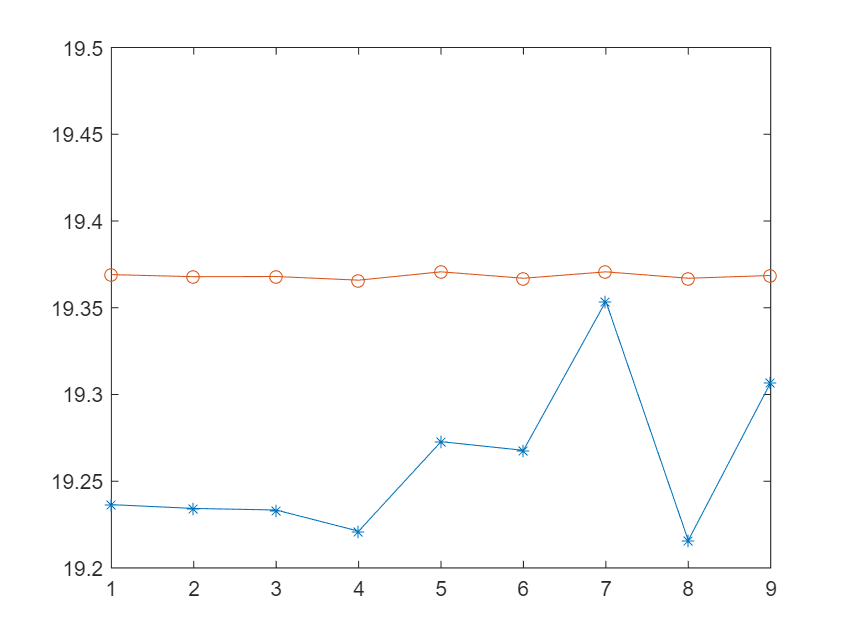

for i = 1:length(diffa1)
    x(i) = diffa1(i)+diffa0(i)*0.6566;
end
hold off

za1 = [19.2322 19.2669 19.2394 19.2538 19.3325 19.2556 19.2397 19.2416 19.2356 19.2372 19.2366];
zp1 = [19.3674 19.3707 19.3681 19.3683 19.3695 19.3736 19.3684 19.3691 19.3691 19.3687 19.3688];
std(za1)

ans =      0.028729


std(zp1)

ans =     0.0016735


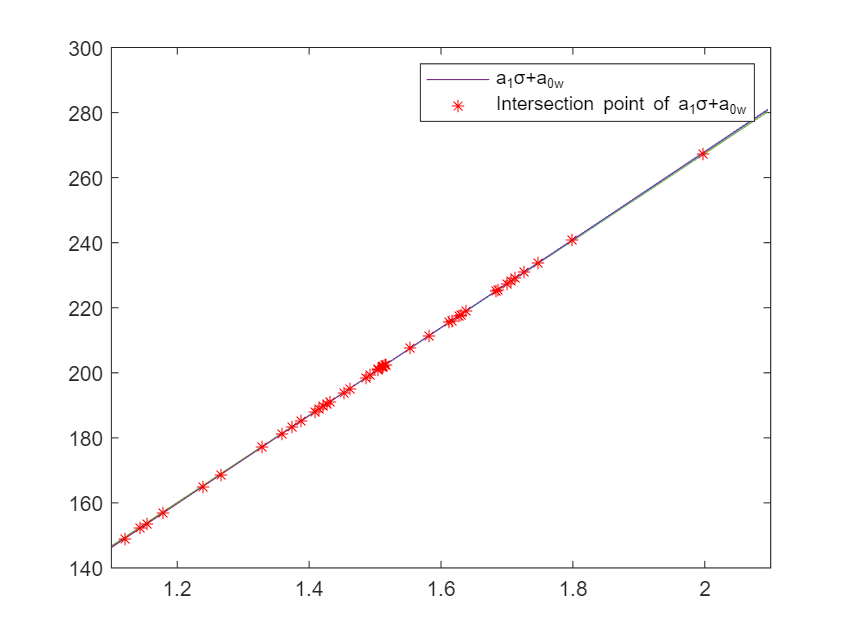


a11 = [135.3178 134.8823 135.2254 135.0448 134.0564 135.0208 135.2214 135.1995 135.2723 135.2517 135.2613];
a00 = [-2.5884 -1.9894 -2.4795 -2.1753 -0.7058 -2.2661 -2.4602 -2.4385 -2.5481 -2.5121 -2.5283];%-2.4385 -2.5481 -2.5121 -2.5283
for n =1:length(a11)
    y = a11(n).*spectrum_frequency+a00(n);
    h1 = plot(spectrum_frequency,y);
    hold on 
end
for i = 1:10
    for n = i+1:11
    [x1, y1] = linecross(a11(i),a00(i),a11(n),a00(n));
    h2 = plot(x1,y1,'*r');
    end
end
xlim([1.1 2.1])
hold off

legend([h1,h2],'a_{1}{\sigma}+a_{0w}','Intersection point of a_{1}{\sigma}+a_{0w}');



za = [19.3366 19.3400 19.3341 19.3050 19.3159 19.3438 19.3369 19.3344 19.3359 19.3403];
zp = [19.3855 19.3866 19.3873 19.3855 19.3849 19.3860 19.3857 19.3858 19.3858 19.3855];
plot(1:10,za,'-*');
hold on
plot(1:10,zp,'-o');
ylim([19.2 19.5])
std(za)

ans =      0.012157


std(zp)

ans =    0.00066533


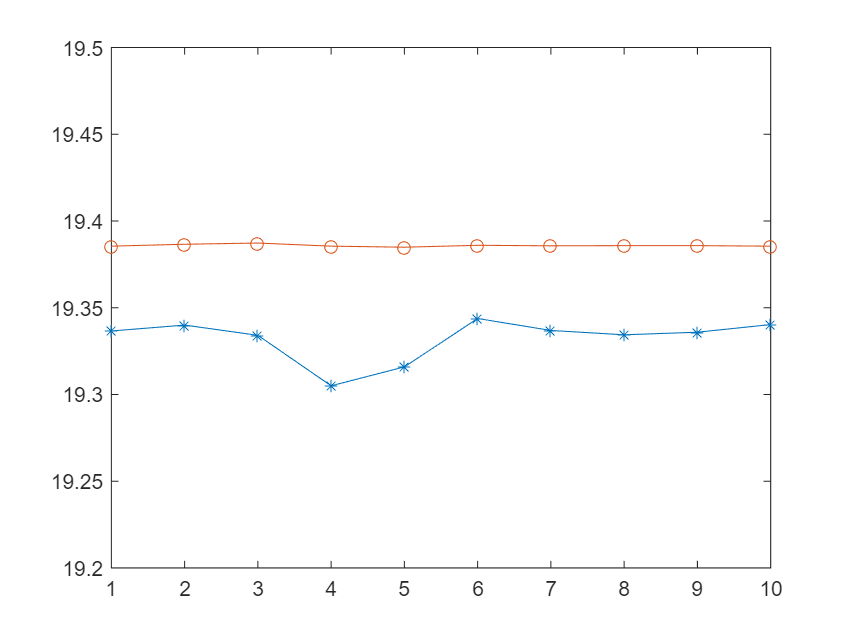

hold off

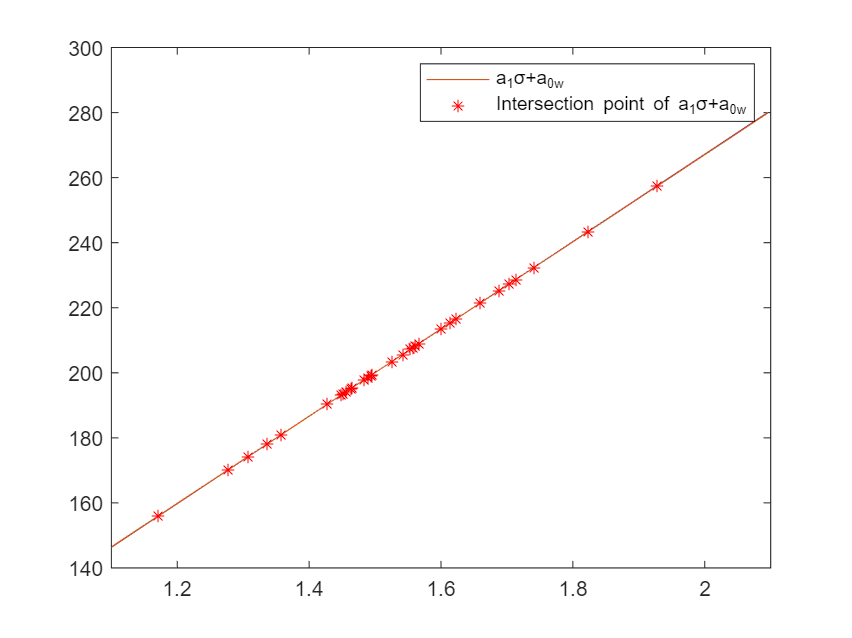


a12 = [133.9626 134.0350 134.3994 134.2622 133.9148 134.0012 134.0310 134.0114 133.9563];% 134.0066
a02 = [-0.8895 -1.0136 -1.5563 -1.3174 -0.8088 -0.9347 -0.9824 -0.9533 -0.8618];% -0.9419
for n =1:length(a12)
    y = a12(n).*spectrum_frequency+a02(n);
    h11 = plot(spectrum_frequency,y);
    hold on 
end
for i = 1:length(a12)-1
    for n = i+1:length(a12)
    [x1, y1] = linecross(a12(i),a02(i),a12(n),a02(n));
    h22 = plot(x1,y1,'*r');
    end
end
xlim([1.1 2.1])
hold off

legend([h11,h22],'a_{1}{\sigma}+a_{0w}','Intersection point of a_{1}{\sigma}+a_{0w}');

%% 已知两条直线的斜率和截距，求交点坐标

function [x,y]=linecross(k1,b1,k2,b2)
  x=[];
  y=[];
  if k1==k2&b1==b2
      disp('chong he');
  elseif k1==k2&b1~=b2
      disp('wu jiao dian');
  else
     x=(b2-b1)/(k1-k2);
     y=k1*x+b1;

  end
end